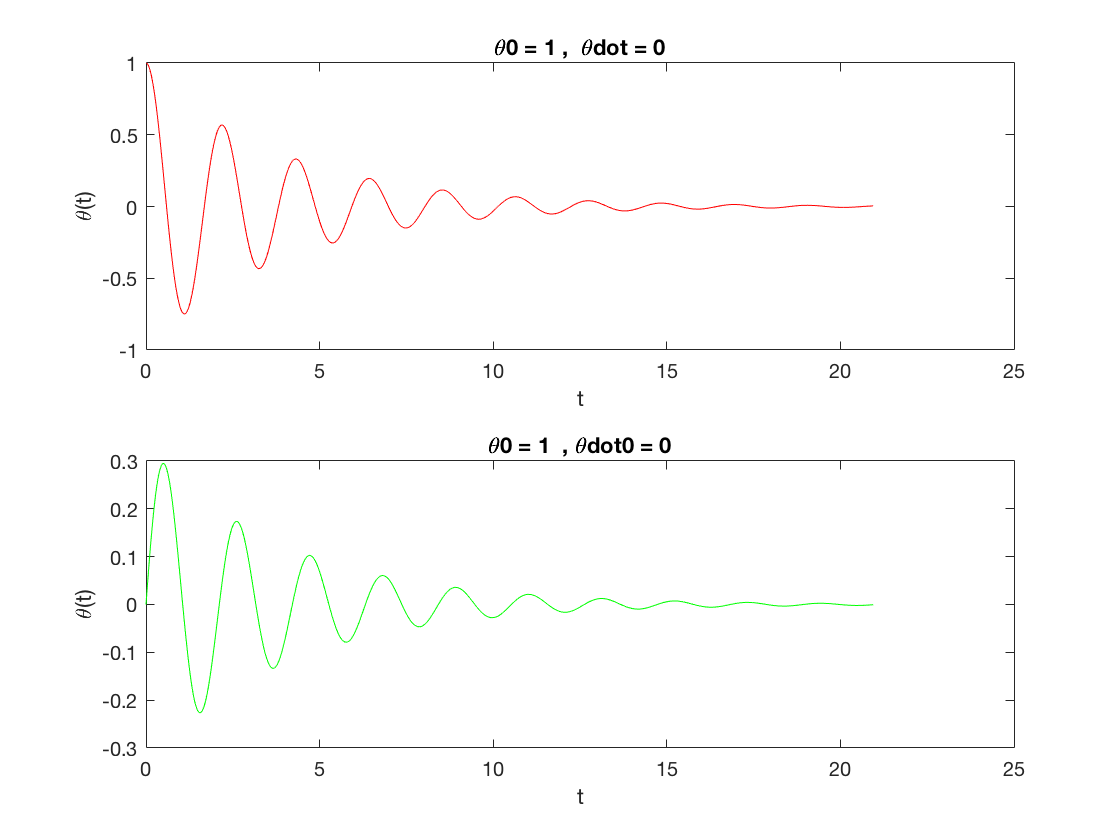

%Linear response to forced oscillation: 
% an external force of the form: 1/m F(t) = A0coswt
%set omega0 = 3, Gamma = 0.5, A0 = 1, freq =2 

[T_1,sol1]=Forced_pendulummodified(1.09, 1,0,0,0.5,2);

[T_2,sol2]=Forced_pendulummodified(1.09, 0,1,0,0.5,2);
figure;
subplot(2,1,1)
plot (sol1(:,1),sol1(:,2), 'r');
title('\theta0 = 1 ,  \thetadot = 0')
xlabel('t')
ylabel('\theta(t)')

subplot(2,1,2)
plot (sol2(:,1),sol2(:,2), 'g');
title('\theta0 = 1  , \thetadot0 = 0')
xlabel('t')
ylabel('\theta(t)')


fprintf('T_1 = %f , freq = %f' , T_1,6.28 ./ T_1);

T_1 = 2.094395 , freq = 2.998479

fprintf('T_2 = %f , freq = %f', T_2, 6.28 ./ T_2);

T_2 = 2.103637 , freq = 2.985305

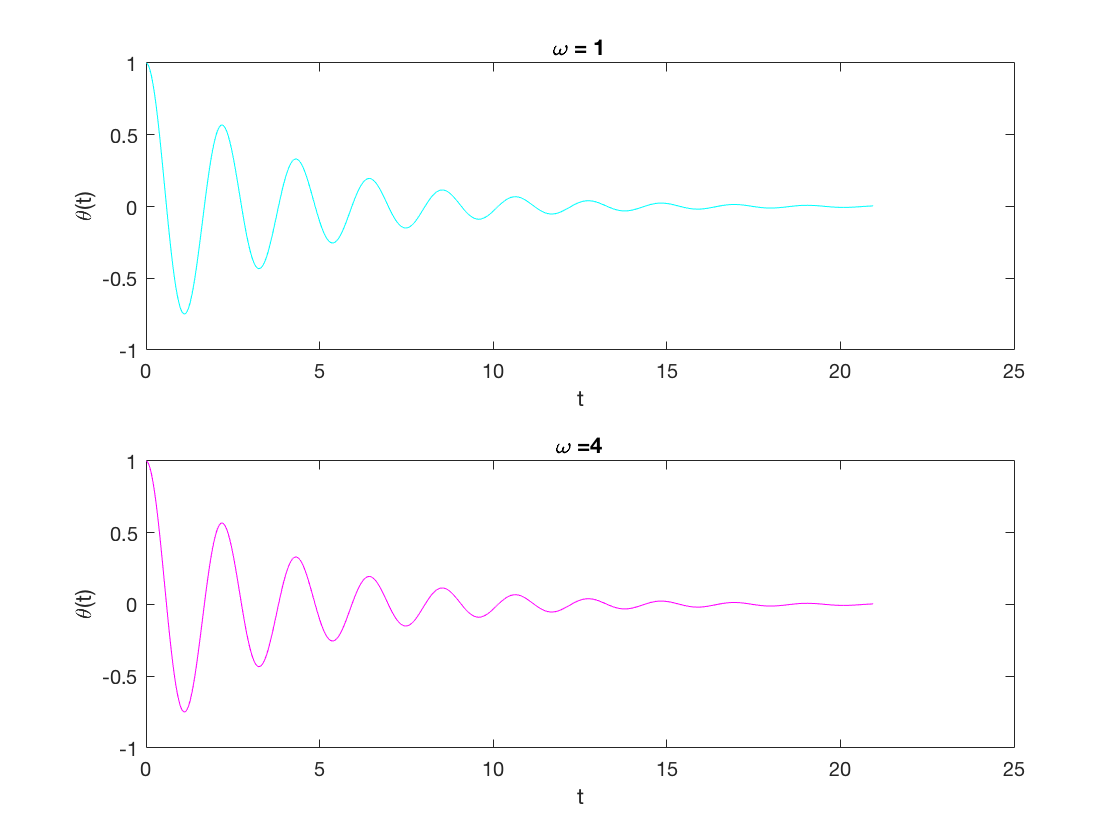

% b) compute theta for freq = 1 and 4



[T_1,sol1]=Forced_pendulummodified(1.09, 1,0,0,0.5,1);
[T_2,sol2]=Forced_pendulummodified(1.09, 1,0,0,0.5,4);

figure;
subplot(2,1,1)
plot (sol1(:,1),sol1(:,2), 'c');
title('\omega = 1')
xlabel('t')
ylabel('\theta(t)')

subplot(2,1,2)
plot (sol2(:,1),sol2(:,2), 'm');
title('\omega =4')
xlabel('t')
ylabel('\theta(t)')

%period and angular freq omega for steady state

fprintf('T_1 = %f , Gamma = %f' , T_1,6.28 ./ T_1);

T_1 = 2.094395 , Gamma = 2.998479

fprintf('T_2 = %f , Gamma = %f', T_2, 6.28 ./ T_2);

T_2 = 2.094395 , Gamma = 2.998479

% c) verify steady state: theta (t) = A(w) cos(wt)+delta
% delta is phase diff b/w applied force and steady state motion


% freq =2:
[T,sol]=Forced_pendulummodified(1.09, 1,0,0,0.5,2);
y = (1 ./ 4).* cos(2 .* sol(:,1));
l=length(sol(:,1)) ;
l=double(l/2); 
delta=sol(end-l:end,2)-y(end-l:end);

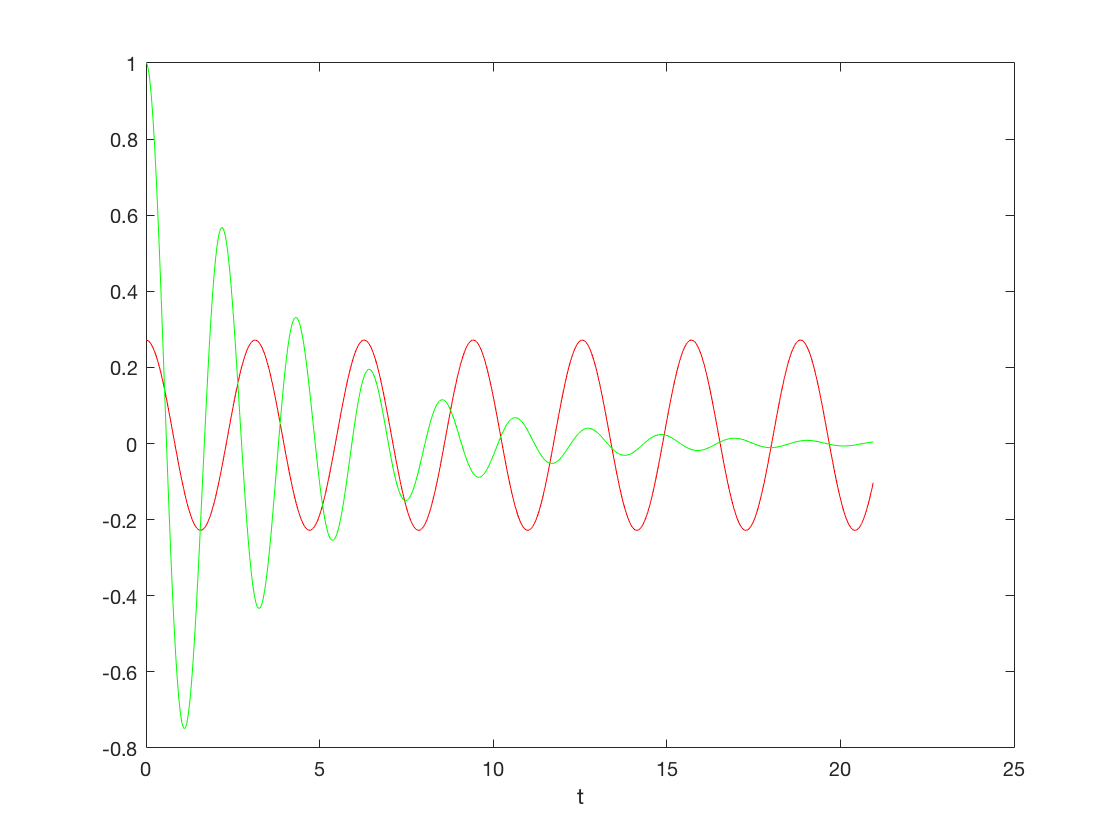

delta=mean(delta);
y=y(:)+delta;

figure;
plot(sol(:,1),y, 'r', sol(:,1),sol(:,2),'g')
xlabel('t');

%compute delta for omega0= 3, freq = 0, 1,2,2.2,2.4,2.6,2.8,3,3.2,3.4
%repeat for Gamma = 1.5
%start with Gamma =0.5
Gamma=0.5; 

freq=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
delta=zeros(length(freq),1);

for i=1:length(freq)
   [T,sol]=Forced_pendulummodified(1.09, 1,0,0,Gamma,freq(i)); 
   y = (1 ./ freq(i)^2).* cos(freq(i) .* sol(:,1));
   l=length(sol(:,1)) ;
   l=double(l/2);
   deltaarray=sol(end-l:end,2)-y(end-l:end);
   delta(i)=mean(deltaarray);
   
end    

% then repeat for Gamma = 1.5 

Gamma2=1.5; 
freq=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
delta1=zeros(length(freq),1);

for i=1:length(freq)
   [T,sol]=Forced_pendulummodified(1.09, 1,0,0,Gamma2,freq(i)); 
   y = (1 ./ freq(i)^2).* cos(freq(i) .* sol(:,1));
   l=length(sol(:,1)) ;
   l=double(l/2);
   deltaarray2=sol(end-l:end,2)-y(end-l:end);
   delta1(i)=mean(deltaarray2);
   
end    

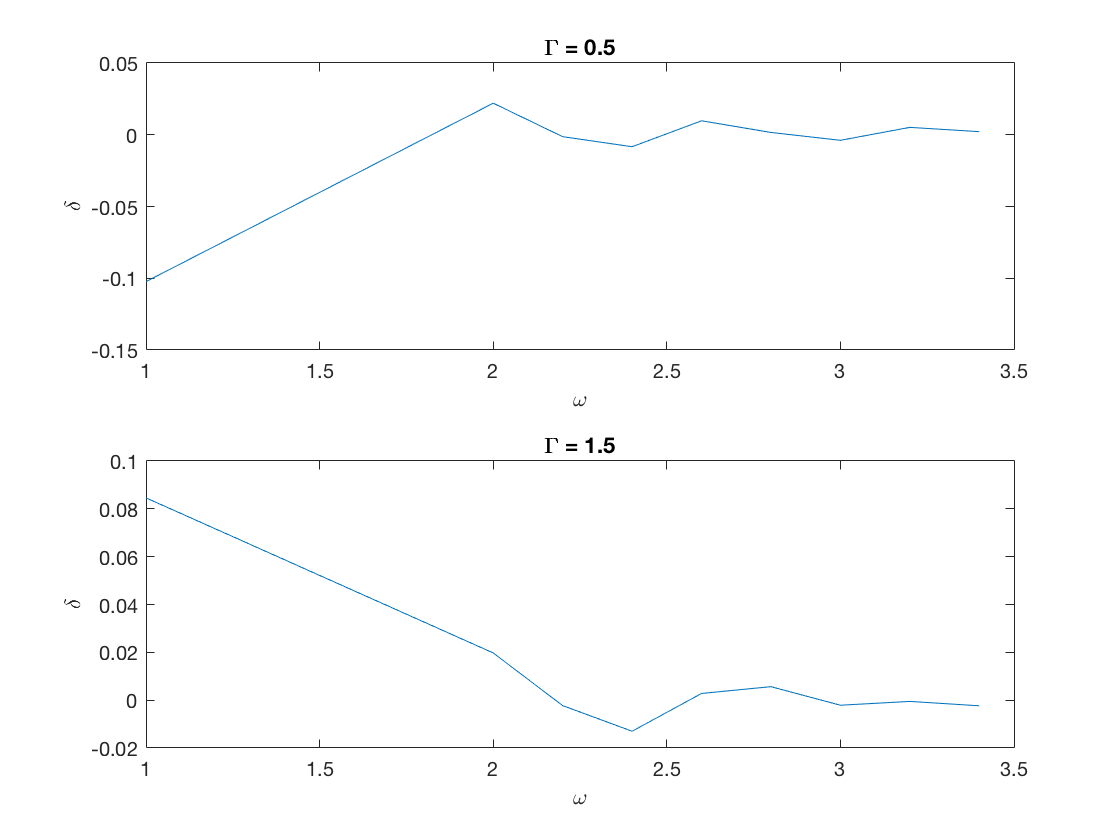


figure;
subplot(2,1,1)
plot(freq,delta);
title('\Gamma = 0.5')
xlabel('\omega');
ylabel('\delta');


subplot(2,1,2)
plot(freq,delta1);
title('\Gamma = 1.5')
xlabel('\omega');
ylabel('\delta');